clear;
disp("Question 1")

Question 1


disp("/////////////////////////////////////////////////")

/////////////////////////////////////////////////


disp("Question 1(a)")

Question 1(a)



disp("|+z> and |-z>:")

|+z> and |-z>:


pz = [1;0]

pz =      1
     0


nz = [0;1]

nz =      0
     1



disp(" ")


disp("First Five values of theta and phi:")

First Five values of theta and phi:


theta = [0, pi/2, pi, 3*pi/2, 2*pi]

theta =          0    1.5708    3.1416    4.7124    6.2832


phi = [0, pi/2, pi, 3*pi/2, 2*pi]

phi =          0    1.5708    3.1416    4.7124    6.2832



disp(" ")


disp("First Five values of nstate:")

First Five values of nstate:


nstate = (cos(theta./2).*pz)+(exp(1i*phi).*sin(theta./2)).*nz

nstate =    1.0000 + 0.0000i   0.7071 + 0.0000i   0.0000 + 0.0000i  -0.7071 + 0.0000i  -1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.7071i  -1.0000 + 0.0000i  -0.0000 - 0.7071i   0.0000 - 0.0000i



disp(" ")


disp("First Five normalized values are:")

First Five normalized values are:


normalized = dot(nstate,nstate)

normalized =      1     1     1     1     1



disp(" ")


disp("Normalized state of |+n> with respect to itself is always 1.")

Normalized state of |+n> with respect to itself is always 1.



disp(" ")


disp("3D plot (with the Five Normalized values):")

3D plot (with the Five Normalized values):


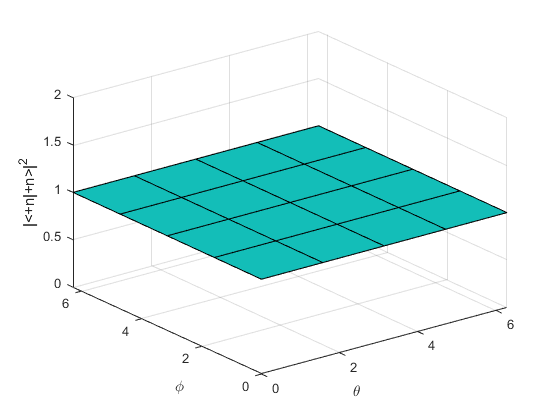

surf(theta,phi,ones(5));
xlabel('\theta')
ylabel('\phi')
zlabel('|<+n|+n>|^2')


disp("/////////////////////////////////////////////////")

/////////////////////////////////////////////////



disp("Question 1(b)")

Question 1(b)


disp("Using the equation:")

Using the equation:


syms theta  phi ;
n = [sin(theta)*cos(phi),sin(theta)*sin(phi),cos(theta)]

$$n = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\sin\left(\theta \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

disp("We find that:")

We find that:


x = [1,0,0]

x =      1     0     0


y = [0,1,0]

y =      0     1     0



disp(" ")


disp("For |+n> to equal |+x>, the following systems must be true:")

For |+n> to equal |+x>, the following systems must be true:


xeq1 = cos(theta) == 0;
xeq2 = sin(theta) == 1;
xeq3 = cos(phi) == 1;
xeq4 = sin(phi) == 0;
disp(xeq1)

$$\cos\left(\theta \right)=0$$

disp(xeq2)

$$\sin\left(\theta \right)=1$$

disp(xeq3)

$$\cos\left(\varphi \right)=1$$

disp(xeq4)

$$\sin\left(\varphi \right)=0$$

disp('Using the MatLab equation solver, I found theta and phi:')

Using the MatLab equation solver, I found theta and phi:


Theta1 = solve(xeq1, theta)

$$Theta1 = \frac{\pi }{2}$$

Theta2 = solve(xeq2, theta)

$$Theta2 = \frac{\pi }{2}$$

Phi1 = solve(xeq3, phi)

$$Phi1 = 0$$

Phi2 = solve(xeq4, phi)

$$Phi2 = 0$$

disp("Thus, theta = pi/2; and phi = 0 ")

Thus, theta = pi/2; and phi = 0 



disp(" ")


disp("For |+n> to equal |+y>, the following systems must be true:")

For |+n> to equal |+y>, the following systems must be true:


yeq1 = cos(theta) == 0;
yeq2 = sin(theta) == 1;
yeq3 = cos(phi) == 0;
yeq4 = sin(phi) == 1;
disp(yeq1)

$$\cos\left(\theta \right)=0$$

disp(yeq2)

$$\sin\left(\theta \right)=1$$

disp(yeq3)

$$\cos\left(\varphi \right)=0$$

disp(yeq4)

$$\sin\left(\varphi \right)=1$$

disp('Using the MatLab equation solver, I found theta and phi:')

Using the MatLab equation solver, I found theta and phi:


Theta1 = solve(yeq1, theta)

$$Theta1 = \frac{\pi }{2}$$

Theta2 = solve(yeq2, theta)

$$Theta2 = \frac{\pi }{2}$$

Phi1 = solve(yeq3, phi)

$$Phi1 = \frac{\pi }{2}$$

Phi2 = solve(yeq4, phi)

$$Phi2 = \frac{\pi }{2}$$

disp("Thus, theta = pi/2; and phi = pi/2 ")

Thus, theta = pi/2; and phi = pi/2 



disp("/////////////////////////////////////////////////")

/////////////////////////////////////////////////



disp("Question 1(c)")

Question 1(c)


theta = 0:pi/59:pi;
phi = 0:pi/59:pi;

pz = cos(reshape(meshgrid(theta),[],1)./2);
nz = exp(1i*reshape(transpose(meshgrid(phi)),[],1)).*sin(reshape(meshgrid(theta),[],1)./2);

disp("First 60 datasets of the Probability of pointing to |+z> and |-z>:")

First 60 datasets of the Probability of pointing to |+z> and |-z>:



probpz = abs(reshape(pz, 60,[])).^2

probpz =     1.0000    0.9993    0.9972    0.9936    0.9887    0.9824    0.9747    0.9657    0.9553    0.9437    0.9308    0.9167    0.9014    0.8849    0.8674    0.8488    0.8293    0.8088    0.7874    0.7652    0.7423    0.7187    0.6944    0.6696    0.6443    0.6187    0.5926    0.5664    0.5399    0.5133    0.4867    0.4601    0.4336    0.4074    0.3813    0.3557    0.3304    0.3056    0.2813    0.2577    0.2348    0.2126    0.1912    0.1707    0.1512    0.1326    0.1151    0.0986    0.0833    0.0692
    1.0000    0.9993    0.9972    0.9936    0.9887    0.9824    0.9747    0.9657    0.9553    0.9437    0.9308    0.9167    0.9014    0.8849    0.8674    0.8488    0.8293    0.8088    0.7874    0.7652    0.7423    0.7187    0.6944    0.6696    0.6443    0.6187    0.5926    0.5664    0.5399    0.5133    0.4867    0.4601    0.4336    0.4074    0.3813    0.3557    0.3304    0.3056    0.2813    0.2577    0.2348    0.2126    0.1912    0.1707    0.1512    0.1326    0.1151    0.0986    0.0833

probnz = abs(reshape(nz, 60,[])).^2

probnz =          0    0.0007    0.0028    0.0064    0.0113    0.0176    0.0253    0.0343    0.0447    0.0563    0.0692    0.0833    0.0986    0.1151    0.1326    0.1512    0.1707    0.1912    0.2126    0.2348    0.2577    0.2813    0.3056    0.3304    0.3557    0.3813    0.4074    0.4336    0.4601    0.4867    0.5133    0.5399    0.5664    0.5926    0.6187    0.6443    0.6696    0.6944    0.7187    0.7423    0.7652    0.7874    0.8088    0.8293    0.8488    0.8674    0.8849    0.9014    0.9167    0.9308
         0    0.0007    0.0028    0.0064    0.0113    0.0176    0.0253    0.0343    0.0447    0.0563    0.0692    0.0833    0.0986    0.1151    0.1326    0.1512    0.1707    0.1912    0.2126    0.2348    0.2577    0.2813    0.3056    0.3304    0.3557    0.3813    0.4074    0.4336    0.4601    0.4867    0.5133    0.5399    0.5664    0.5926    0.6187    0.6443    0.6696    0.6944    0.7187    0.7423    0.7652    0.7874    0.8088    0.8293    0.8488    0.8674    0.8849    0.9014    0.9167


disp('Probability of measurement yielding 1 (using the previous 60 datasets):')

Probability of measurement yielding 1 (using the previous 60 datasets):


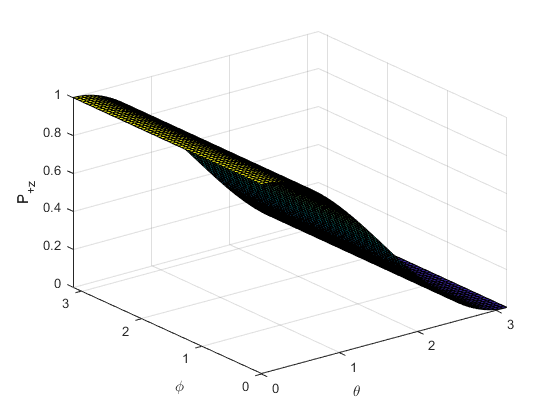

surf(theta,phi,probpz);
xlabel('\theta')
ylabel('\phi')
zlabel('P_{+z}')


disp(' ')


disp('Probability of measurement yielding -1 (using the previous 60 datasets):')

Probability of measurement yielding -1 (using the previous 60 datasets):


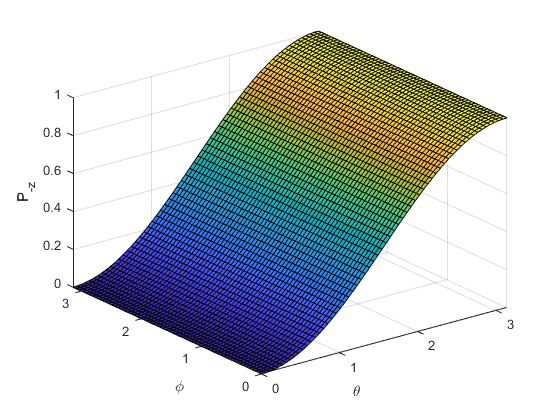

surf(theta,phi,probnz);
xlabel('\theta')
ylabel('\phi')
zlabel('P_{-z}')


disp(' ')


disp("Graphing Both probabilities in the same 3D plot:")

Graphing Both probabilities in the same 3D plot:


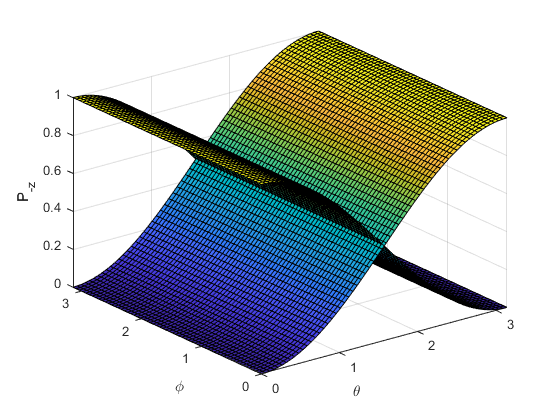

surf(theta,phi,probpz);
hold on;
surf(theta,phi,probnz);
hold off;
xlabel('\theta')
ylabel('\phi')
zlabel('P_{-z}')